# EJERCICIOS TEMA 6 

## E1A

### Respuesta: 

####     PrimSegDeriv

####     SplineCub

**a) **

Calculamos v y a 

clc, clear, clf

% Datos 
t = 0:2:30;
x = [61 72.8 81.9 87.9 90.9 90.8 87.3 80.5 70.4 56.9 39.9 19.4 -4.6 -32.2 -63.3 -98];
y = [65 46.7 30.3 15.8 3.2 -7.4 -15.8 -22.1 -26.2 -28.1 -27.9 -25.3 -20.5 -13.4 -4.1 7.6];


[vx,ax] = PrimSegDeriv(t,x);
[vy,ay] = PrimSegDeriv(t,y);

v = sqrt(vx.^2 + vy.^2);
a = sqrt(ax.^2 + ay.^2);
T = table(x',y',t',v',a');
T.Properties.VariableNames = {'x(m)','y(m)','t(s)','v(m/s)','a(m/s^2)'};
disp(T)

    x(m)     y(m)     t(s)    v(m/s)    a(m/s^2)
    _____    _____    ____    ______    ________

       61       65      0     11.656    0.74582 
     72.8     46.7      2     10.127    0.82538 
     81.9     30.3      4      8.598    0.90898 
     87.9     15.8      6     7.1388    0.88776 
     90.9      3.2      8     5.8451    0.92229 
     90.8     -7.4     10     4.8345     1.0124 
     87.3    -15.8     12     4.4873    0.97788 
     80.5    -22.1     14     4.9609    0.99153 
     70.4    -26.2     16     6.0877     1.0124 
     56.9    -28.1     18     7.6368     1.0204 
     39.9    -27.9     20     9.4011      1.061 
     19.4    -25.3     22     11.278     1.0335 
     -4.6    -20.5     24     13.239      1.068 
    -32.2    -13.4     26     15.237     1.0335 
    -63.3     -4.1     28     17.267     1.08

**b) **

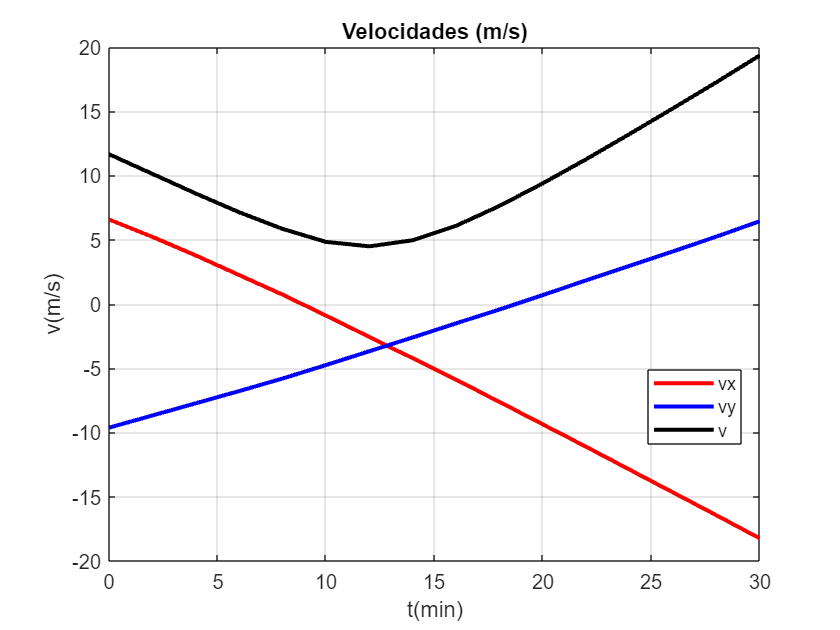

plot(t,vx,'-r','LineWidth',2)
hold on
plot(t,vy,'-b','LineWidth',2)
plot(t,v,'-k','LineWidth',2)
grid on 

legend('vx','vy','v','location','best')
xlabel('t(min)')
ylabel('v(m/s)')
title('Velocidades (m/s)')
hold off

**c) **

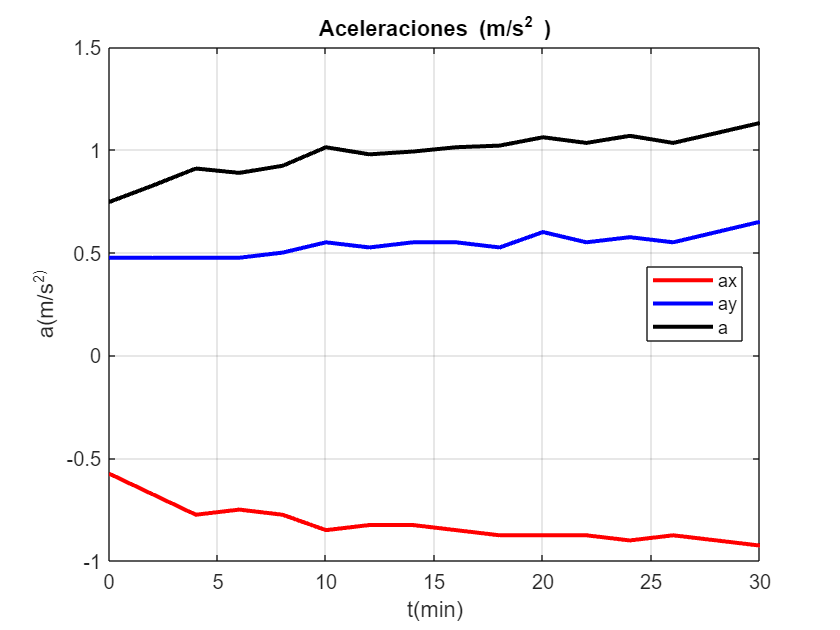

plot(t,ax,'-r','LineWidth',2)
hold on
plot(t,ay,'-b','LineWidth',2)
plot(t,a,'-k','LineWidth',2)
grid on 

legend('ax','ay','a','location','best')
xlabel('t(min)')
ylabel('a(m/s^2)')
title('Aceleraciones (m/s^2 )')
hold off

**d)** Para calcular el mínimo de la velocidad hacemos interpolación inversa. Primero calculamos la derivada de la  velocidad (que no es lo mismo que la aceleración): 

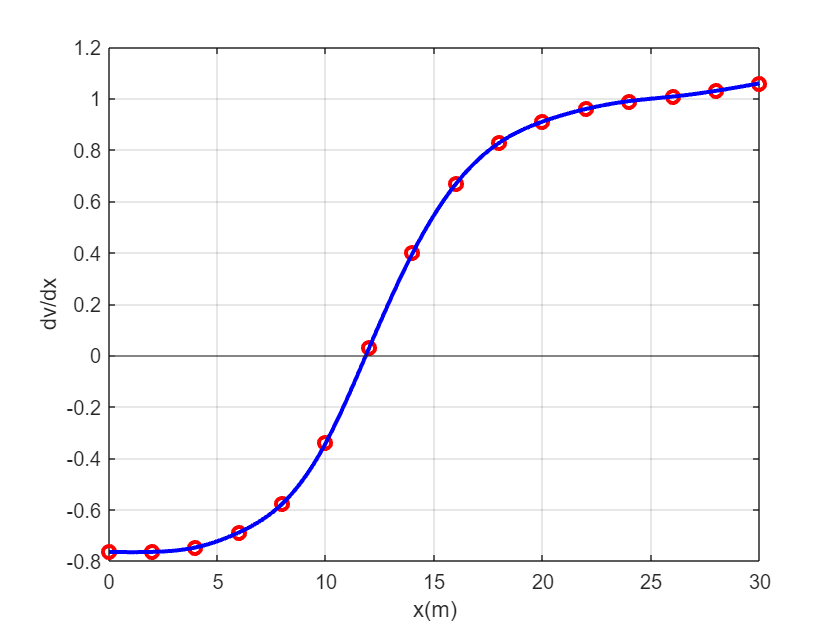

[dv, ~] = PrimSegDeriv(t,v);
tp = linspace(0+0.01,30-0.01,100);
for i=1:100
    yp(i) = SplineCub(t,dv,tp(i));
end

plot(t,dv,'or','LineWidth',2)
hold on
plot(tp, yp,'b','LineWidth',2)
grid on 

yline(0)
xlabel('x(m)')
ylabel('dv/dx')
hold off

Tomamos los 3 puntos próximos a donde la derivada de v se hace cero para interpolar

tpi = t(1,6:8);
dvi = dv(1,6:8);
tmin = SplineCub(dvi,tpi,0);
fprintf('La velocidad mínima se produce a los %6.4f s.\n',tmin)

La velocidad mínima se produce a los 11.8292 s.


vmin = SplineCub(t,v,tmin);
fprintf('La velocidad mínima es de %6.4f m/s\n',vmin)

La velocidad mínima es de 4.4847 m/s


## E2A

### Respuesta: 

####     PySDerDes

####     SplineCub

####     NewtonINT

**a)** Cálculo de las componentes de la velocidad y la aceleración 

clc, clear, clf 

% Datos 
t = [0 1 2 2.5 3 3.5 4 4.5 5 5.5 6 7 8 ];
x = [0 4.1 14.9 25.4 37.5 48.4 59 69.6 80.3 92.2 103.5 115.3 119.8]; 
y = [31.6 22.3 7.1 2 3.54 7.6 10 8.2 4.3 1.8 5.7 21.2 31.1];


[vx, ax] = PySDerDes(t,x);
[vy, ay] = PySDerDes(t,y);
v = sqrt(vx.^2+vy.^2);
a = sqrt(ax.^2+ay.^2);

T = table(t', x', y', v, a);
T.Properties.VariableNames = {'t(s)','x(m)','y(m)','v(m/s)','a(m/s^2)'};
disp(T)

    t(s)    x(m)     y(m)    v(m/s)    a(m/s^2)
    ____    _____    ____    ______    ________

      0         0    31.6    6.3941     21.039 
      1       4.1    22.3    14.338     8.9275 
      2      14.9     7.1    21.227     16.575 
    2.5      25.4       2    22.879      27.32 
      3      37.5    3.54    23.672     11.165 
    3.5      48.4     7.6     22.45     6.7476 
      4        59      10    21.208       16.8 
    4.5      69.6     8.2    22.049     8.4095 
      5      80.3     4.3    23.489     7.3756 
    5.5      92.2     1.8    23.242     25.712 
      6     103.5     5.7    21.644     20.758 
      7     115.3    21.2     15.09     9.2005 
      8     119.8    31.1    7.1507      24.67 



**b) **

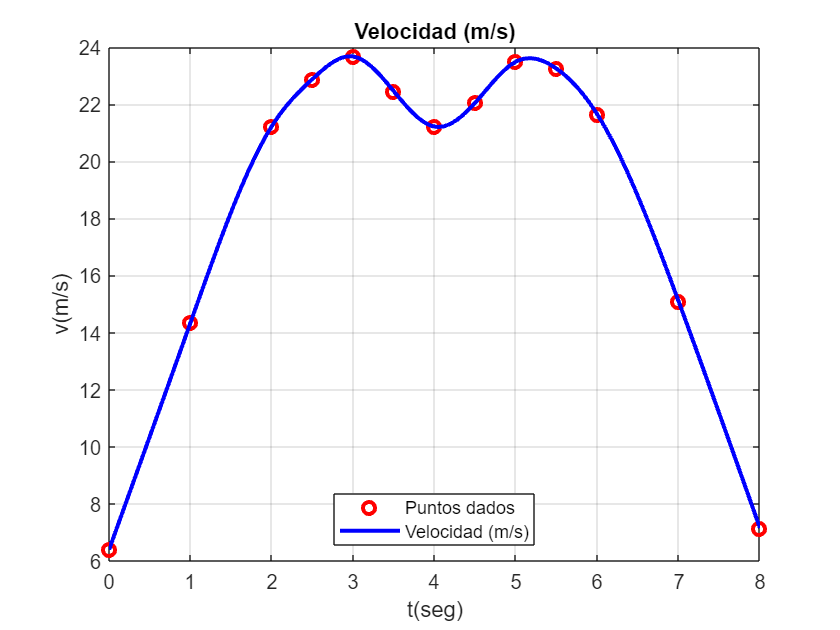

plot(t,v,'or','LineWidth',2);
hold on

tp = linspace(0.001,7.999,100);
for i = 1:100
 yp(i) = SplineCub(t,v,tp(i));
end
plot(tp,yp,'b','LineWidth',2)
grid on 

xlabel('t(seg)')
ylabel('v(m/s)')
title('Velocidad (m/s)')
legend('Puntos dados','Velocidad (m/s)','location','south')
hold off

**c) **

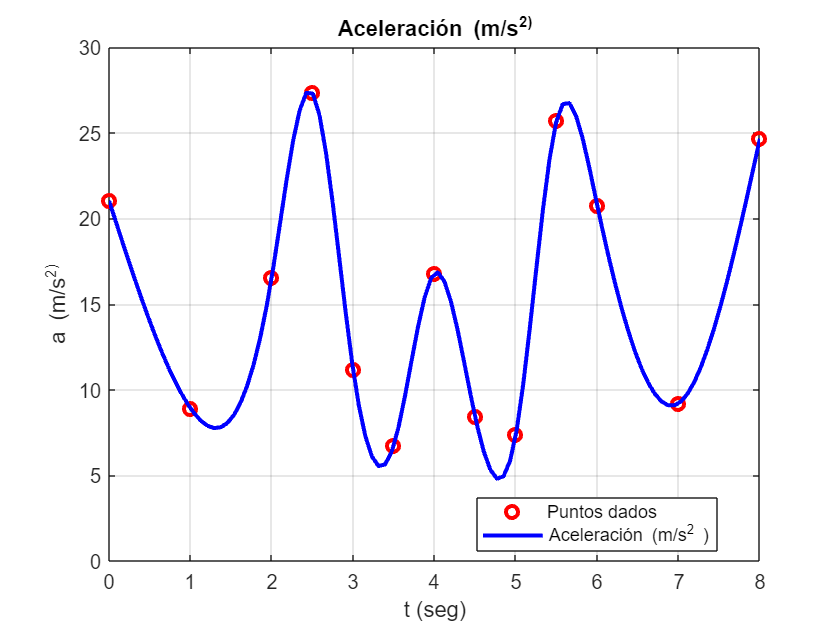

plot(t,a,'or','LineWidth',2)
hold on
for i = 1:100
 yp(i) = SplineCub(t,a,tp(i));
end
plot(tp,yp,'b','LineWidth',2)
grid on 

xlabel('t (seg)')
ylabel('a (m/s^2)')
title('Aceleración (m/s^2)')
legend('Puntos dados','Aceleración (m/s^2 )','location','best')
hold off

**d) **

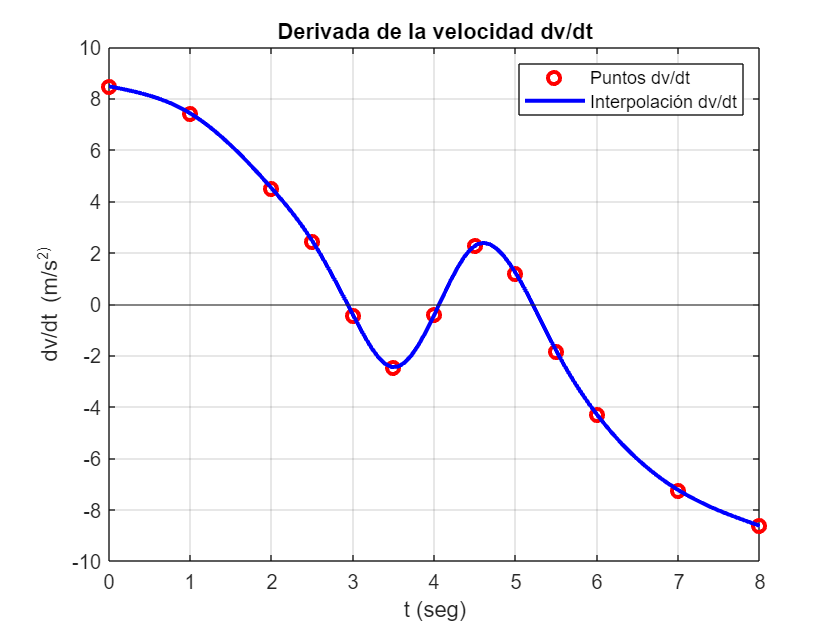

dv = PySDerDes(t,v);
plot(t,dv,'or','LineWidth',2)
hold on
for i = 1:100
 ydv(i) = SplineCub(t,dv,tp(i));
end
plot(tp,ydv,'b','LineWidth',2)
grid on
yline(0)

xlabel('t (seg)')
ylabel('dv/dt (m/s^2)')
title('Derivada de la velocidad dv/dt')
legend('Puntos dv/dt','Interpolación dv/dt')
hold off

Escogemos 3 puntos próximos donde se encuentra el máximo y realizamos interpolación inversa: 

tm = t(1,4:6);
dv = dv';
dvm = dv(1,4:6);
v = v';
vm = v(1,4:6);
tmax = NewtonINT(dvm,tm,0);
fprintf('El primer momento en que se anula la velocidad es en t = %6.4f s\n',tmax)

El primer momento en que se anula la velocidad es en t = 2.9100 s


vmax = SplineCub(t,v,tmax);
fprintf('La velocidad máxima es de %6.4f m/s\n',vmax)

La velocidad máxima es de 23.6660 m/s


tmax = 8

## E1B

### Respuesta: 

**a) **

clc, clear, clf 

% Datos 
x = 0 : 24 : 360; 
y = [0 -0.111 -0.216 -0.309 -0.386 -0.441 -0.473 -0.479 -0.458 -0.412 -0.345 -0.263 -0.174 -0.090 -0.026 0];
E = 29e6;
I = 720;

[~,ydd] = PrimSegDeriv(x,y);
M = -ydd * E * I;
T = table(x',y',M');
T.Properties.VariableNames = {'x(in)', 'y(in)', 'M (lb·ft)'};
disp (T)

    x(in)    y(in)      M (lb·ft) 
    _____    ______    ___________

       0          0    -2.0123e-09
      24     -0.111     -2.175e+05
      48     -0.216      -4.35e+05
      72     -0.309       -5.8e+05
      96     -0.386     -7.975e+05
     120     -0.441    -8.3375e+05
     144     -0.473     -9.425e+05
     168     -0.479    -9.7875e+05
     192     -0.458    -9.0625e+05
     216     -0.412    -7.6125e+05
     240     -0.345    -5.4375e+05
     264     -0.263    -2.5375e+05
     288     -0.174     1.8125e+05
     312      -0.09       7.25e+05
     336     -0.026     1.3775e+06
     360          0       2.03e+06



**b) **

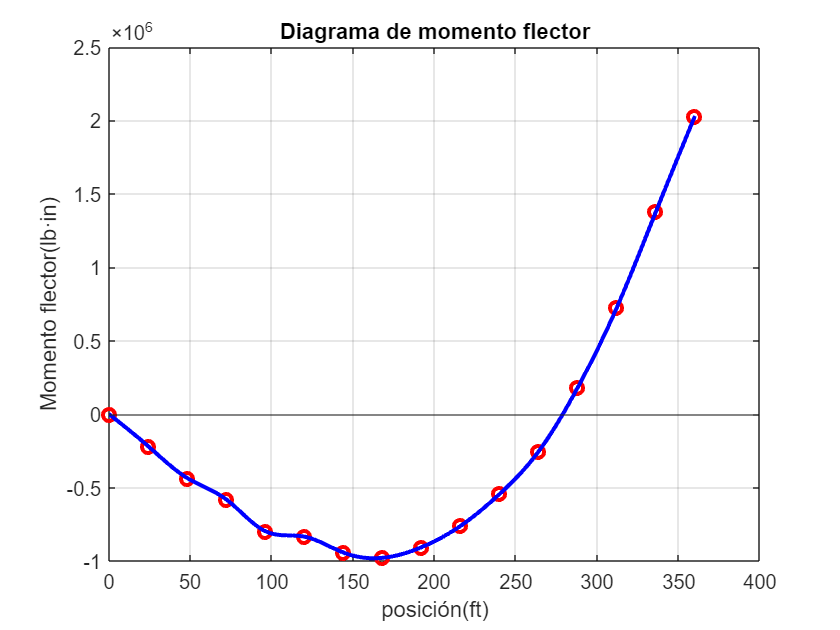

plot(x,M,'or','LineWidth',2,'HandleVisibility','off')
hold on

xp = linspace(min(x)+0.01,max(x)-0.01,100);
for i=1:100
 yp(i) = SplineCub(x,M,xp(i));
end
plot(xp,yp,'b','LineWidth',2)
yline(0)
grid on 

xlabel('posición(ft)')
ylabel('Momento flector(lb·in)')
title('Diagrama de momento flector')
hold off

**c) **  Para calcular el punto donde se anula el momento flector tomamos los 3 puntos de la gráfica próximos al que  se anula y hacemos interpolación inversa: 

xi = x(1,12:14);
Mi = M(1,12:14);
x0 = NewtonINT(Mi,xi,0);
fprintf('El momento flector se anula en x = %6.4f in\n',x0)

El momento flector se anula en x = 278.5185 in


**d)** Interpolamos con splines.

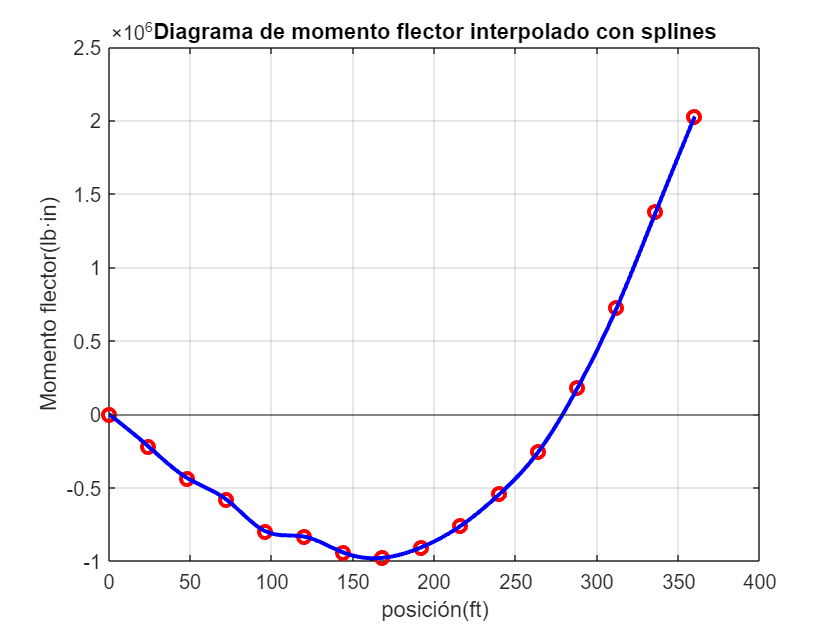

plot(x,M,'or','LineWidth',2)
hold on

xp = linspace(min(x)+0.1,max(x)-0.1,100);
for i = 1:100
 yp(i) = SplineCub(x,M,xp(i));
end
plot (xp, yp, '-b','LineWidth',2)
yline(0)
grid on 

xlabel('posición(ft)')
ylabel('Momento flector(lb·in)')
title('Diagrama de momento flector interpolado con splines')
hold off

Hacemos interpolación inversa con spline sobre los mismos 3 puntos del apartado anterior

x02 = SplineCub(Mi,xi,0);
fprintf('El momento flector con splines se anula en x = %6.4f in\n',x02)

El momento flector con splines se anula en x = 278.4105 in


dif = abs((x0 -x02)/x0)*100;
fprintf('Se diferencian en %6.4f %%\n',dif)

Se diferencian en 0.0388 %


No coinciden aunque el error es muy pequeño. La ligera diferencia está dada por los distintos grados de los  polinomios de interpolación (2º grado en el apartado c) y 3er grado en el d) con splines). Ninguno es más  preciso que el otro. 

## E2B

### Respuesta: 

**a) **

clc , clear, clf 

% Datos 
x = 0:0.375:3;
y = [0 -0.2571 -0.9484 -1.9689 -3.2262 -4.6414 -6.1503 -7.7051 -9.275]/100;
[theta, d2ydx] = PrimSegDeriv(x,y);
T1 = table(x',y', theta');
T1.Properties.VariableNames = {'x(m)','y(m)','theta (m/m)'};
disp(T1)

    x(m)       y(m)       theta (m/m)
    _____    _________    ___________

        0            0    -0.0010667 
    0.375    -0.002571     -0.012645 
     0.75    -0.009484     -0.022824 
    1.125    -0.019689     -0.030371 
      1.5    -0.032262     -0.035633 
    1.875    -0.046414     -0.038988 
     2.25    -0.061503     -0.040849 
    2.625    -0.077051     -0.041663 
        3     -0.09275     -0.042065 



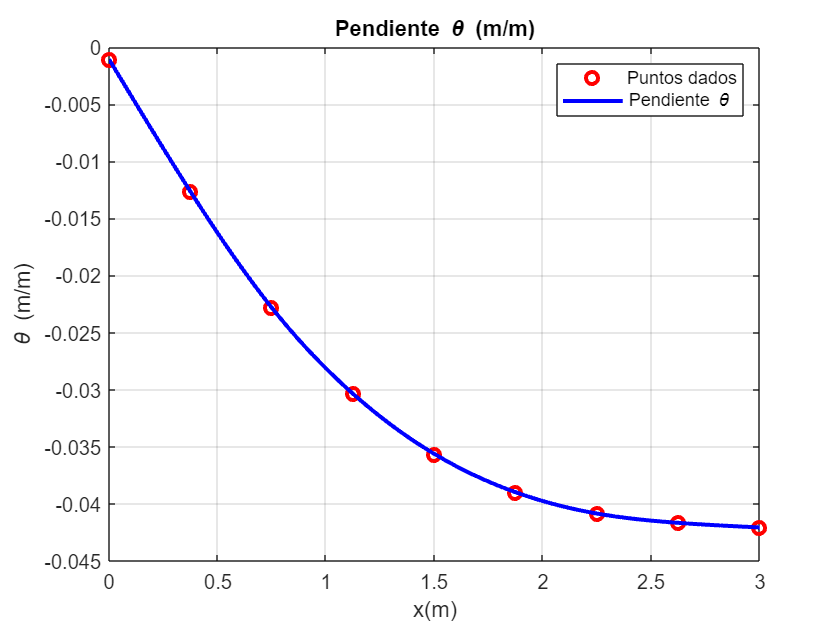

xp = linspace(min(x)+0.001,max(x)-0.001,100);
for i=1:100
 yp(i) = SplineCub(x,theta,xp(i));
end
plot(x,theta,'or','LineWidth',2)
hold on
plot(xp,yp,'b','LineWidth',2)
grid on 

xlabel('x(m)')
ylabel('{\theta} (m/m)')
title ('Pendiente {\theta} (m/m)')
legend('Puntos dados','Pendiente {\theta}')
hold off

**b) **

E = 200*1e9;
I = 0.0003;
M = E * I * d2ydx;
T2 = table(x',y', M');
T2.Properties.VariableNames = {'x(m)','y(m)','M(N·m)'};
disp(T2)

    x(m)       y(m)         M(N·m)   
    _____    _________    ___________

        0            0    -2.3006e+06
    0.375    -0.002571    -1.8526e+06
     0.75    -0.009484    -1.4046e+06
    1.125    -0.019689    -1.0103e+06
      1.5    -0.032262    -6.7371e+05
    1.875    -0.046414    -3.9979e+05
     2.25    -0.061503    -1.9584e+05
    2.625    -0.077051         -64427
        3     -0.09275          66987



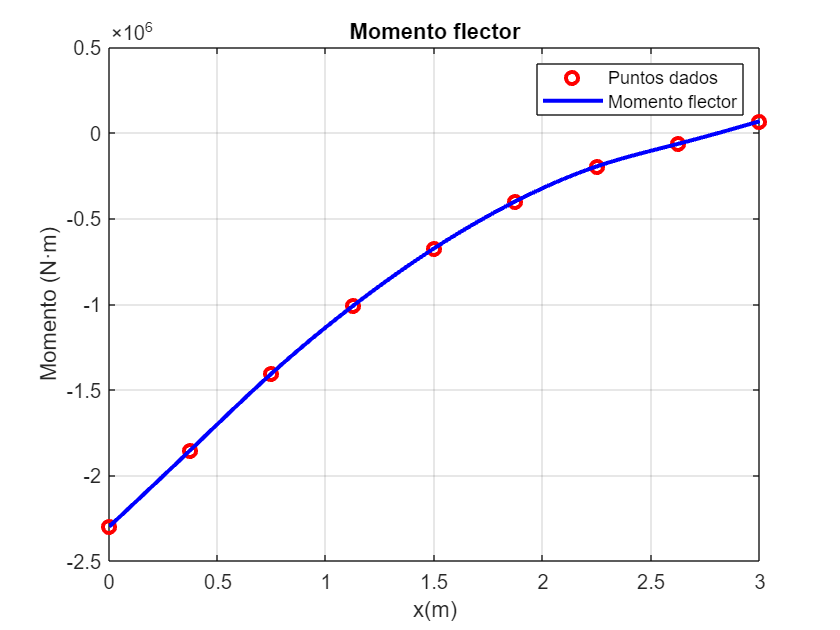

for i=1:100
 ym(i) = SplineCub(x,M,xp(i));
end
plot(x,M,'or','LineWidth',2)
hold on
plot(xp,ym,'b','LineWidth',2)
grid on 

xlabel('x(m)')
ylabel('Momento (N·m)')
title ('Momento flector')
legend('Puntos dados','Momento flector')
hold off

**c) **

[V, w] = PrimSegDeriv(x,M);
T3 = table(x',y', V');
T3.Properties.VariableNames = {'x(m)','y(m)','V (N)'};
disp(T3)

    x(m)       y(m)         V (N)   
    _____    _________    __________

        0            0    1.1947e+06
    0.375    -0.002571    1.1947e+06
     0.75    -0.009484     1.123e+06
    1.125    -0.019689    9.7451e+05
      1.5    -0.032262    8.1408e+05
    1.875    -0.046414    6.3716e+05
     2.25    -0.061503    4.4715e+05
    2.625    -0.077051    3.5044e+05
        3     -0.09275    3.5044e+05



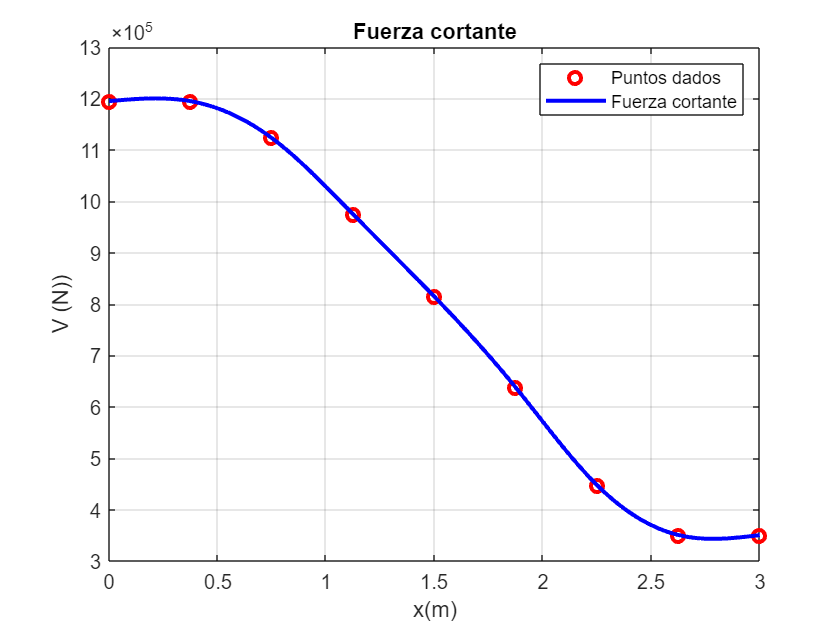

for i=1:100
 yv(i) = SplineCub(x,V,xp(i));
end
plot(x,V,'or','LineWidth',2)
hold on
plot(xp,yv,'b','LineWidth',2)
grid on 

xlabel('x(m)')
ylabel('V (N))')
title ('Fuerza cortante')
legend('Puntos dados','Fuerza cortante')
hold off 

**d) **

w = -w;
T4 = table(x',y', w');
T4.Properties.VariableNames = {'x(m)','y(m)','w (N/m)'};
disp(T4)

    x(m)       y(m)         w (N/m)  
    _____    _________    ___________

        0            0    -3.8229e+05
    0.375    -0.002571     3.3114e-09
     0.75    -0.009484     3.8229e+05
    1.125    -0.019689      4.096e+05
      1.5    -0.032262     4.4601e+05
    1.875    -0.046414     4.9759e+05
     2.25    -0.061503     5.1579e+05
    2.625    -0.077051     4.2116e-08
        3     -0.09275    -5.1579e+05



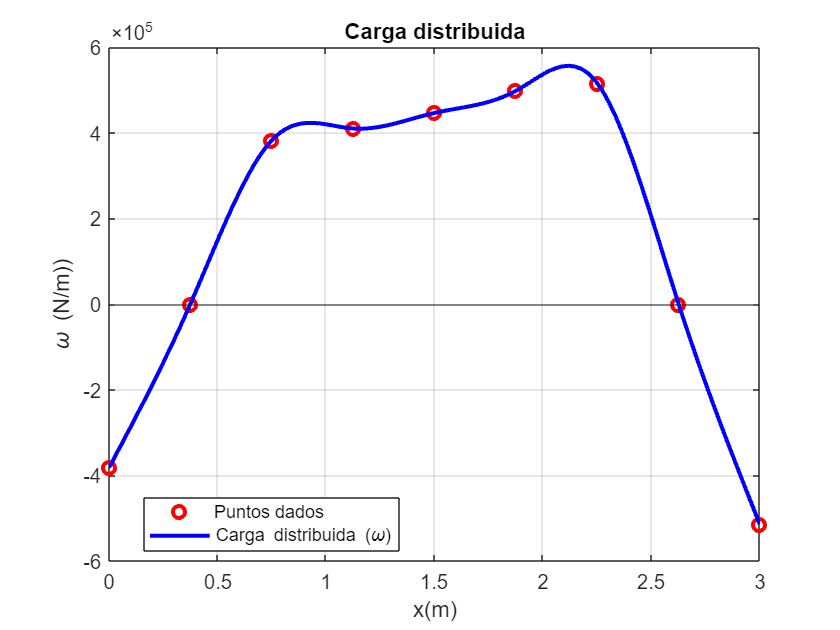

plot(x,w,'or','LineWidth',2)
hold on
for i=1:100
 yw(i) = SplineCub(x,w,xp(i));
end
plot(xp,yw,'b','LineWidth',2)
yline(0)
grid on 

xlabel('x(m)')
ylabel('{\omega} (N/m))')
title ('Carga distribuida')
legend('Puntos dados','Carga distribuida ({\omega})','Location','best')